# Autorzy sprawozdania

Piotr Patek, 324 789

Damian Baraniak, 324 851

## Wczytanie pliku i analiza spektrogramu sygnału wejściowego

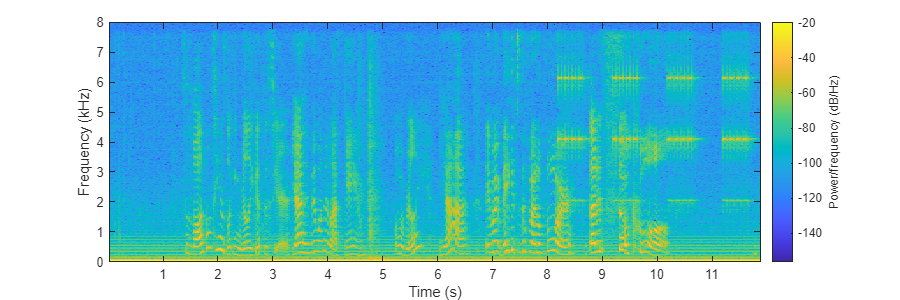

[x, fs] = audioread('noised.wav');
win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x, blackman(win_size), win_size/2, [], fs, 'yaxis')

Na podstawie spektogramu, postanowiono wyciąć częstotliwości do 500Hz oraz pasm ok 2kHz, 4kHz, 6kHz.

## Przygotowanie i analiza charakterystyki filtrów

### Filtr dolnoprzepustowy

% częstotliwość odcięcia
fc = 500;
% stromość zbocza
fb = 50;
F_low = f_lowpass(fc, fb, fs);
sum(F_low)

ans = 1

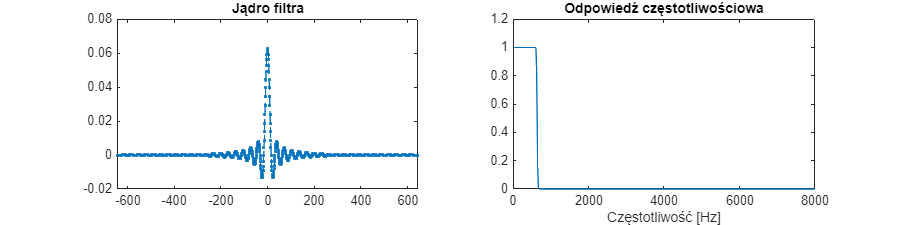

filtstat(F_low, fs);

### Filtr górnoprzepustowy

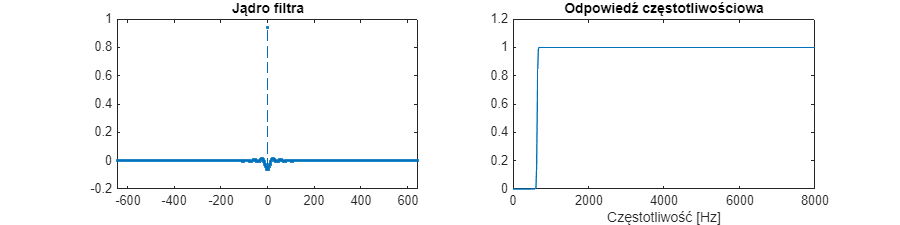

F_high = f_highpass(fc, fb, fs);
filtstat(F_high, fs);

### Filtr pasmowoblokujący

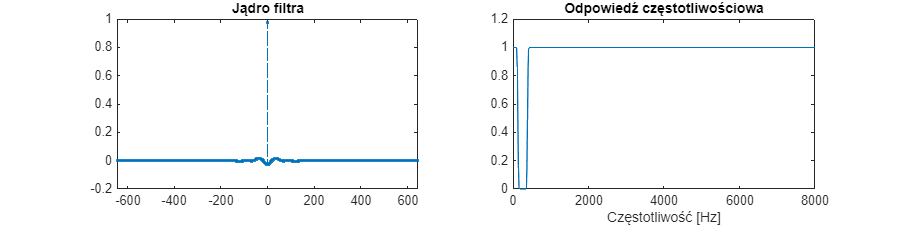

fl = 100;
fh = 300;
F_band = f_bandstop(fl, fh, fb, fs);
filtstat(F_band, fs);

## Filtracja sygnału

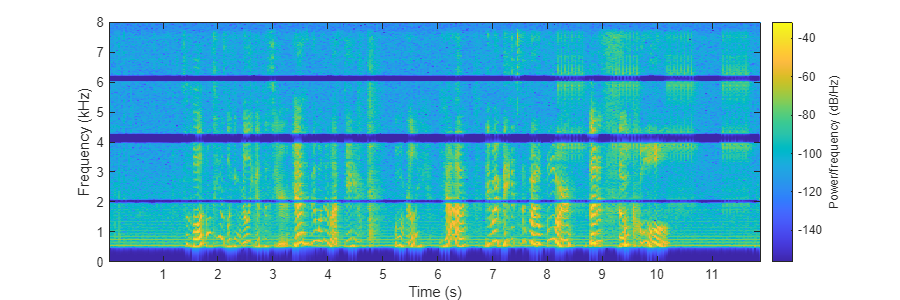

% x_filtered = conv(x, F_low, 'same') + conv(x, F_high, 'same') + conv(x, F_band, 'same');
F_a = f_highpass(500,10,fs);
F_b = f_bandstop(1950,2100,20,fs);
F_c = f_bandstop(3950,4300,20,fs);
F_d = f_bandstop(6000,6250,20,fs);
fab = conv(F_a,F_b, 'same');
fcd = conv(F_c,F_d, 'same');
filter = conv(fab,fcd,'same');
x_filtered = conv(x,filter, 'same');

win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x_filtered, blackman(win_size), win_size/2, [], fs, 'yaxis')

## Odtworzenie przefiltrowanego sygnału

sound(x_filtered, fs);

## Zapis pliku wyjściowego

audiowrite('output.wav', x_filtered, fs);

## Implementacja filtrów

### Argumenty:

- fc - częstotliwość graniczna (Hz)

- fl, fh - częstotliwości graniczne filtra pasmowego (Hz)

- fb - szerokość pasma przejściowego (Hz)

- fs - częstotliwość próbkowania sygnału filtrowanego (Hz)

function H = f_lowpass(fc, fb, fs)
    K=1;
    fc = fc/fs;
    fb = fb/fs;
    M = round(4/fb);
    if (mod(M,2)==1)
        M = M+1;
    end
    H = zeros(1,M+1);

    for i=1:M
        if i == M/2
            H(i+1) = 2*pi*fc*K;
        else
            H(i+1) = K*sin(2*pi*fc*(i-M/2))/(i-M/2)*(0.42-0.5*cos(2*pi*i/M)+0.08*cos(4*pi*i/M));
        end
    end
    K = 1/sum(H);
    H = K*H;
end

function F = f_highpass(fc, fb, fs)
F_lp = f_lowpass(fc,fb,fs);
F_hp = -F_lp;
F_hp(ceil(length(F_lp)/2)) = F_hp(ceil(length(F_lp)/2))+1;
F = F_hp;
end

function F = f_bandstop(fl, fh, fb, fs)
    F = f_lowpass(fl, fb, fs) + f_highpass(fh, fb, fs);
end

## Funkcje wyświetlające dane

function filtstat(f, fs)
    nfft = 1000;
    
    f_ex = zeros(1, nfft);
    f_ex(1:size(f, 2)) = f;
        
    y = fft(f_ex);
    f_base = linspace(0, fs/2, nfft/2+1);
    amp = abs(y(1:nfft/2+1));
    phase = angle(y(1:nfft/2+1));
    
    figure('Position', [10 10 1200 300]);
    subplot(121);
    f_pad = [zeros(1, 5), f, zeros(1, 5)];
    t_pad = (1:length(f_pad)) - round(length(f_pad) / 2);
    plot(t_pad, f_pad, '.--');
    title("Jądro filtra");
    subplot(122);
    plot(f_base, amp);
    title("Odpowiedź częstotliwościowa");
    xlabel("Częstotliwość [Hz]");
end

## Podsumowanie

Porównując sygnał przed i po filtracji można stwierdzić, że szum o niskiej częstotliwości został znacznie zredukowany. Podobnie na sile straciły odgłosy alarmu. Chociaż oba dźwięki są dalej słyszalne to nie przeszkadzają w odsłuchiwaniu jak to było w oryginalnym nagraniu. Niestety wycinanie kontkrentych częstoliwości miało również negatywny wpływ na jakość głosów rozmawiających osób, rozmowa wydaje się cichsza czy mniej wyrazista, ale dalej w pełni zrozumiała i niezakłócona alarmem.